# Bush 2008 Stimulus as a Function of Income and Family Status

Taking advantage of [**snw_stimulus_checks_bush**](https://github.com/FanWangEcon/PrjOptiSNW/blob/master/PrjOptiSNW/fgov/snw_stimulus_checks_bush.m) from the [**PrjOptiSNW Package**,](https://fanwangecon.github.io/PrjOptiSNW/) this function presents stimulus checks at different income levels for households with different children count and martial status. The function considers the bush stimulus checks from the [Economic Stimulus Act of 2008](https://en.wikipedia.org/wiki/Economic_Stimulus_Act_of_2008). IRS information provides information at the [Economic Stimulus Payment Information Center](https://www.irs.gov/newsroom/economic-stimulus-payment-information-center).

Note that the Bush stimulus is a tax rebate, so we compute tax liability based on [snw_tax_liability](https://github.com/FanWangEcon/PrjOptiSNW/blob/master/PrjOptiSNW/fgov/G:\repos\PrjOptiSNW\PrjOptiSNW\doc\fgov\snw_tax_liability.m). 

The Stimulus policy is expressed in the following formula, first four components ($M$ is marital status, equals to 1 for married, 0 for unmarried, $K$ is the number of kids, $Y$ is pre-tax income) :

- 
$$\text{MinChk}(M) 
= 
300\cdot\left(
    1+M
    \right)$$


- 
$$\text{CappedRebate}(Y,K,M)
= 
\min\Big(
        \text{TaxLiability}\left(Y,K,M\right)
        ,
        600\cdot\left(1+M\right)
    \Big)$$


- 
$$\text{PhaseOut}(Y,M) 
= 
\max\Big(
        0,
        Y-75000\cdot(1+M)
        \Big)\cdot 0.05$$


- 
$$\text{KidsChk}(K)
= 
300\cdot K$$


Overall Tax-rebate Stimulus is:


$$\text{Bush08StimulusTaxRebate} = \max\Bigg(
    \max\bigg(
    \text{MinChk}(M) 
    ,
    \text{CappedRebate}(Y,K,M)
    \bigg)
    + \text{KidsChk}(K)
    - \text{PhaseOut}(Y,M) 
    ,
    0
\Bigg)$$


## Bush Stimulus Checks for Unmarried Households

Check base amount per adult and per child for the first and second rounds. 

Visualize stimulus check amounts.

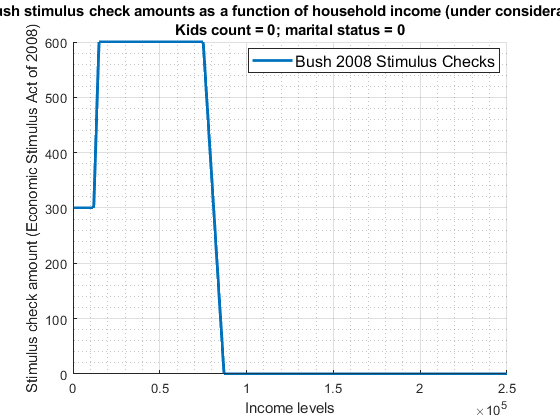

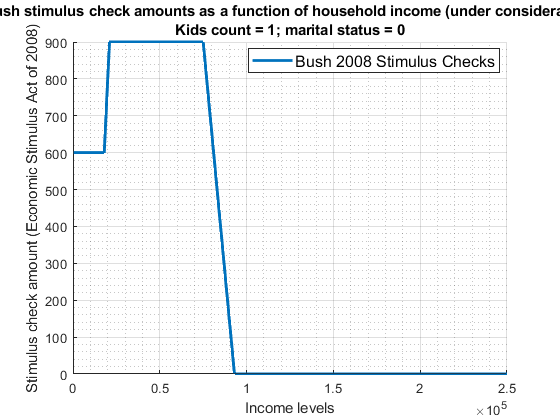

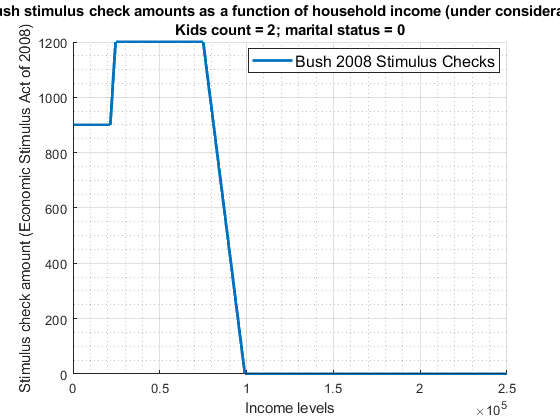

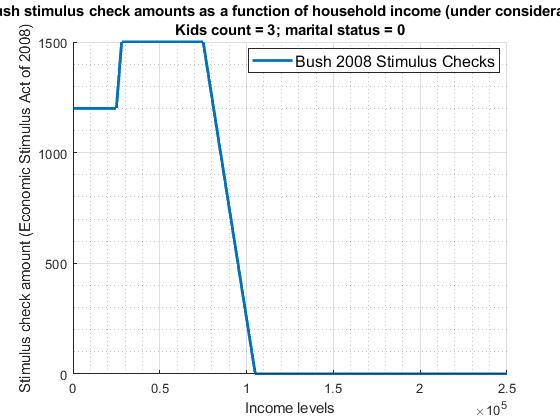

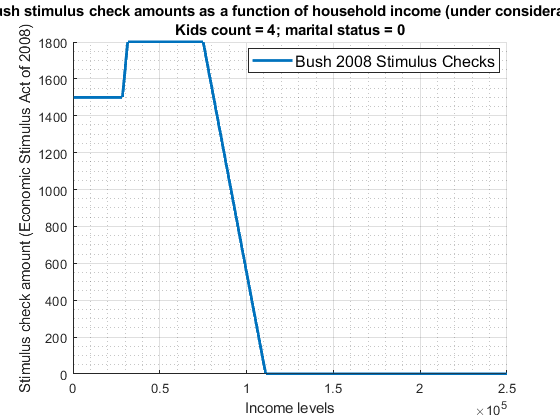

bl_visualize = true;
[fl_stimulus_adult, fl_stimulus_child] = deal(600, 300);
bl_marital = 0;
for it_kids=0:1:4
    snw_stimulus_checks_bush(it_kids, bl_marital, fl_stimulus_adult, fl_stimulus_child, bl_visualize);
end

## Bush Stimulus Checks for Married Households

Visualize stimulus check amounts.

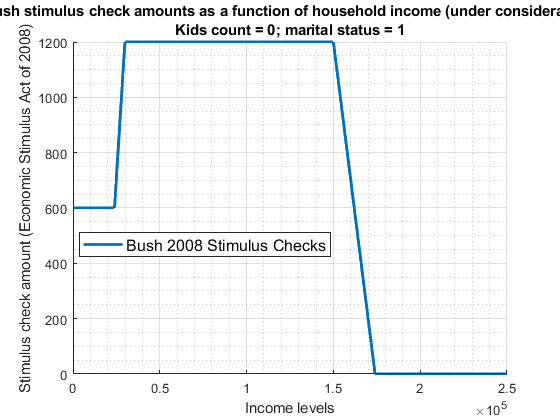

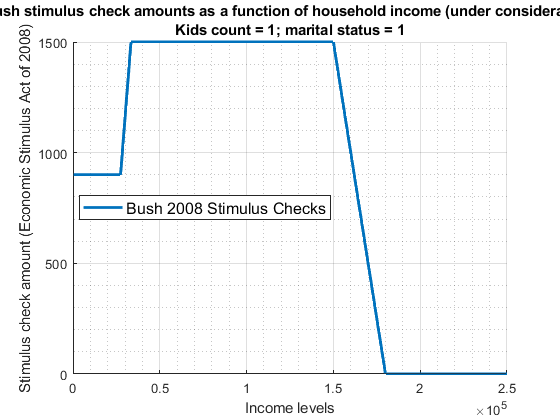

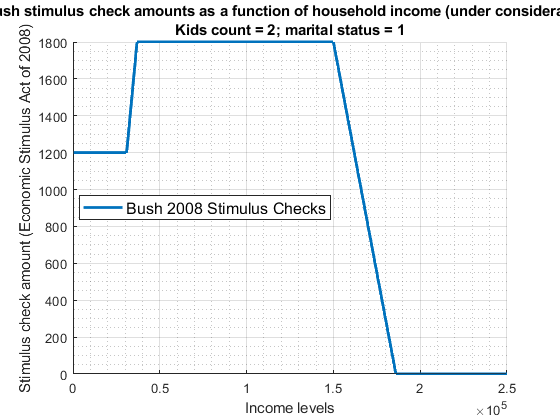

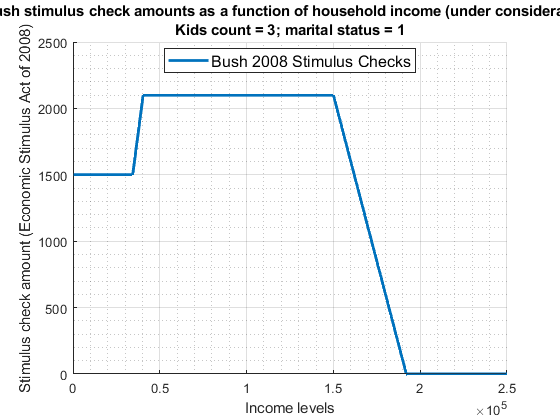

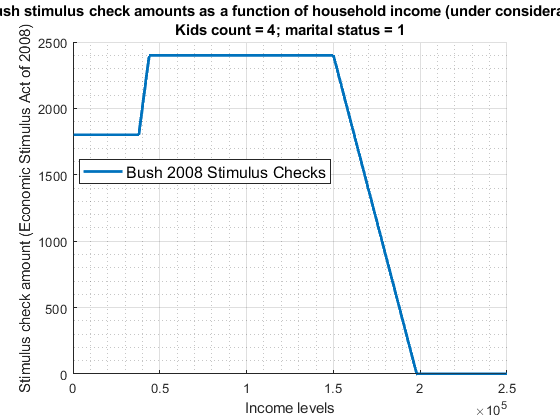

[fl_stimulus_adult, fl_stimulus_child] = deal(600, 300);
bl_marital = 1;
for it_kids=0:1:4
    snw_stimulus_checks_bush(it_kids, bl_marital, fl_stimulus_adult, fl_stimulus_child, bl_visualize);
end